# 绘制多个 y 轴

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

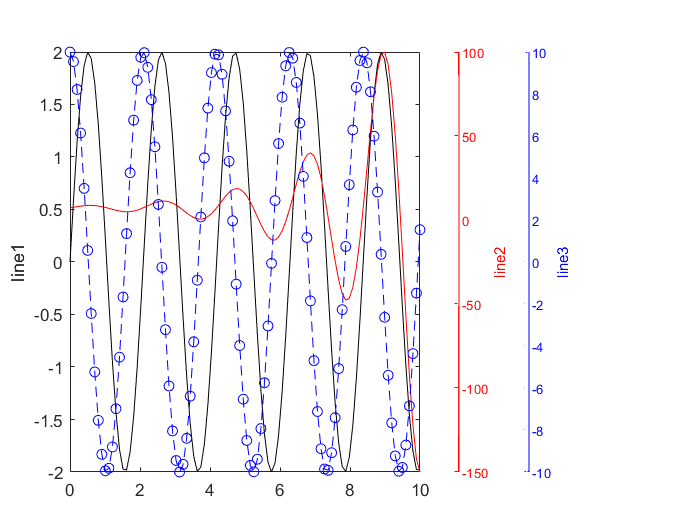

clear; clc; close all;
%% yyaxis 官方帮助文档 demo
x = linspace(0, 10, 100);
y1 = 2*sin(3*x);
y2 = sin(3*x) .* exp(0.5*x);
%% 三个纵坐标演示，更多纵坐标可以按照此方法类推
y3 = 10*cos(3*x);
% 三条线绘制到一起，注意数据都标准化到 y1 范围
maxY1 = max(y1);
maxY2 = max(y2);
maxY3 = max(y3);
minY1 = min(y1);
minY2 = min(y2);
minY3 = min(y3);
% 归一化
newY2 = (y2 - minY2)/(maxY2 - minY2);   
% 反归一化
newY2 = newY2*(maxY1 - minY1) + minY1;  
newY3 = (y3 - minY3)/(maxY3 - minY3);
newY3 = newY3*(maxY1 - minY1) + minY1;
% 画线
% 控制 axes 的大小和位置，注意是相对于figure的，范围为[0, 1]
h1 = axes('position', [0.1 0.1 0.5 0.8]);   
plot(x, y1, 'k', x, newY2, 'r', x, newY3, 'ob--')
ylabel('line1');
% 绘制另外两个空的坐标轴
h2 = axes('position', [0.65 0.1 0.005 0.8]); 
% 重复绘制，曲线颜色用白色，和figure背景色一致，看不出来即可
plot(x, y2, 'w')
% 颜色，位置，曲线标签
set(h2, 'YColor', 'r', 'YAxisLocation', 'right', 'XTick', [])
% 边界显示不清楚，所以画一条线
hold on
limX2 = get(h2, 'Xlim');
limY2 = get(h2, 'Ylim');
plot([limX2(2), limX2(2)], limY2, 'r');
hold off
% 取消边框
box off
ylabel('line2');
%
h3 = axes('position', [0.75 0.1 0.005 0.8]); 
plot(x, y3, 'w')
set(h3, 'YColor', 'b', 'YAxisLocation', 'right', 'XTick', [])
hold on
limX3 = get(h3, 'Xlim');
limY3 = get(h3, 'Ylim');
plot([limX3(2), limX3(2)], limY3, 'b');
hold off
box off
ylabel('line3');
% figure背景设置成白色
set(gcf, 'color', 'white'); 
% 取消坐标轴的颜色，和figure统一
set(h1, 'color', 'none');
set(h2, 'color', 'none');
set(h3, 'color', 'none'); 